# 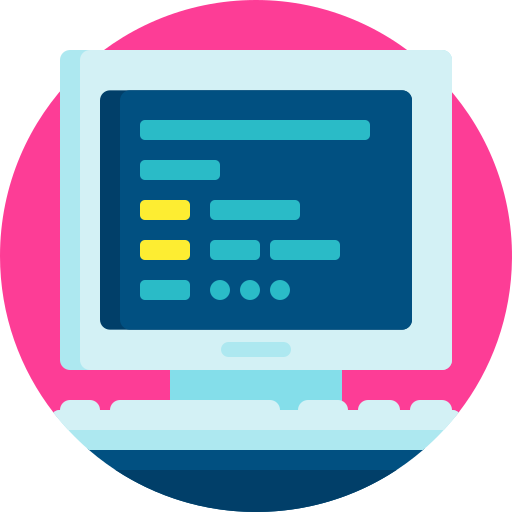

# Virtual Lab 9 - Pose control of a differentially-steered robot

### This Virtual Lab covers Chapter 8 of the notes.

- This Virtual Lab will require both pen-on-paper work, as well as the use of MATLAB coding. The intention is to be able to solve the problems on paper (as you would in a Test/Exam) and then ratify the result using MATLAB.

- Make sure to save this file somewhere where you can access it again later, e.g. Google Drive/OneDrive/MATLAB Drive (or on your PC if you are working on a laptop). 

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on right`.

- Each Section of this Live Script must be run individually. You can run Sections by using the `Run Section` button under the `LIVE EDITOR` ribbon (at the top of the screen), or using CNTL+ENTER (Windows) or CMD+ENTER (macOS).

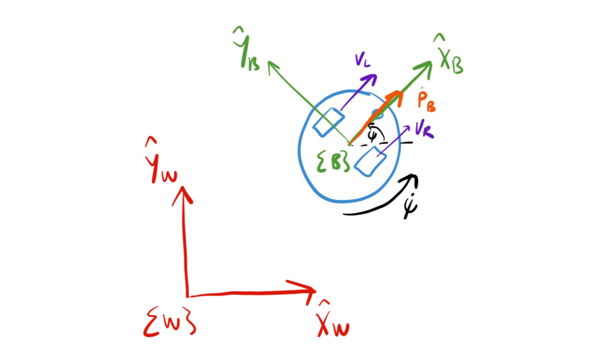

*Figure 1: Representation of differentially-steered robot in frame {W}.*

## Robot setup

We will make use of the Robotic Systems Toolbox to sort out the forward kinematics.

d = 1; %m
r = 0.5; %m
phi_dot_lim = 20; %rad/s
robot = differentialDriveKinematics( TrackWidth=d, WheelRadius=r,WheelSpeedRange=[-phi_dot_lim,phi_dot_lim] )

robot =   differentialDriveKinematics with properties:

      VehicleInputs: 'WheelSpeeds'
         TrackWidth: 1
        WheelRadius: 0.5000
    WheelSpeedRange: [-20 20]


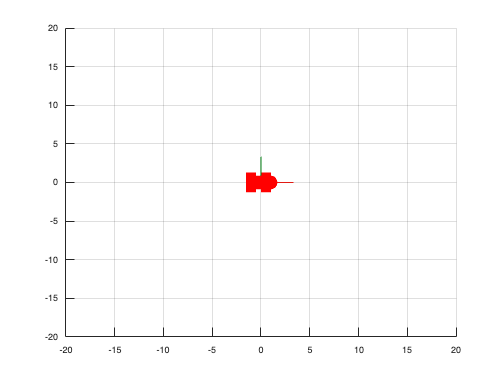


robotPose = [0 0 0]';

figure
plotTrVec = [robotPose(1:2); 0];    %3D position of robot
plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation
plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);

axis([-20 20 -20 20])
grid on

Note that we have added wheel velocity limits of $\pm 20$rad/s. This will be important later when we start applying feedback control (our robot will have finite rotational and translational velocity limits).

#### Question 1: Given the parameters above, if the robot was to experience pure translation (no rotation), what is the maximum obtainable linear velocity?

%Code block (if required)


#### Question 2: Given the parameters above, if the robot was to experience pure rotation (no translation), what is the maximum obtainable angular velocity?

%Code block (if required)


v = 10

## Robot forward kinematics

Recall that we can express the forward kinematics of our wheeled robot as


$$\left[\matrix{\dot{p}_x \cr \dot{p}_y \cr \dot{\psi}}\right]=\left[\matrix{\cos (\psi) v \cr \sin(\psi)v \cr \dot\psi }\right],$$


where $v=\frac{r}{2}(\dot\phi_L+\dot\phi_R)$, and $\dot\psi=\frac{r}{d}(\dot\phi_R-\dot\phi_L)$. $\{v,\dot\psi\}$ are our high-level velocities that we will manipulate. 

Express the relationship above, between $\{v,\dot\psi\}$ and $\{\dot\phi_L,\dot\phi_R\}$ in the form

$\left[\matrix{v \cr \dot\psi}\right]={\bf A} \left[\matrix{\dot\phi_L \cr \dot\phi_R}\right]$.

#### Question 3: Find ${\bf A}^{-1}$, the matrix that maps the input signals, $\{v,\dot\psi\}$, to the desired wheel velocities, $\{\dot\phi_L,\dot\phi_R\}$. 

*Hint: use the symbolic toolbox.*

%Add code here


We will use this later in the Virtual Lab when we need to map our control signals to the wheel speeds.

## Position error 

Let's assume that ${^W{\bf p}^*}=[10~~10~~0]^T$

p_des = [10 10 0]';

Update your previous figure to include this point. Indicate it with a red circle (see [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html#btzptin) if need be).

%Add code here


### World-frame position error

The world-frame position error is simply the difference between the current position, ${^W{\bf p}}$, and desired position, ${^W{\bf p}^*}$,

${^W{\bf e}_p}={^W{\bf p}^*}-{^W{\bf p}}$.

Using our current position, we can determine the world-frame position error 

p = [robotPose(1:2); 0];

$$invA = \left(\begin{array}{cc} \frac{1}{r} & -\frac{d}{2\,r}\\ \frac{1}{r} & \frac{d}{2\,r} \end{array}\right)$$

e_p_wf = p_des - p

So our robot is required to move $10$ metres in the positive $\hat{\bf x}_W$-axis and $10$ metres in the positive $\hat{\bf y}_W$-axis direction. Ensure that you are comfortable with this geometry before moving on.

### Body-frame position error

If we know our world-frame position error and current orientation, $\psi$, we can derive the corresponding body-frame position error using

${^B{\bf e}_p}={^B{\bf R}_W}{^W{\bf e}_p}={^B{\bf R}_W}\left({^W{\bf p}^*}-{^W{\bf p}})$,

where ${^B{\bf R}_W$ is the rotation matrix that encodes the orientation of $\{W\}$ with respect to $\{B\}$.

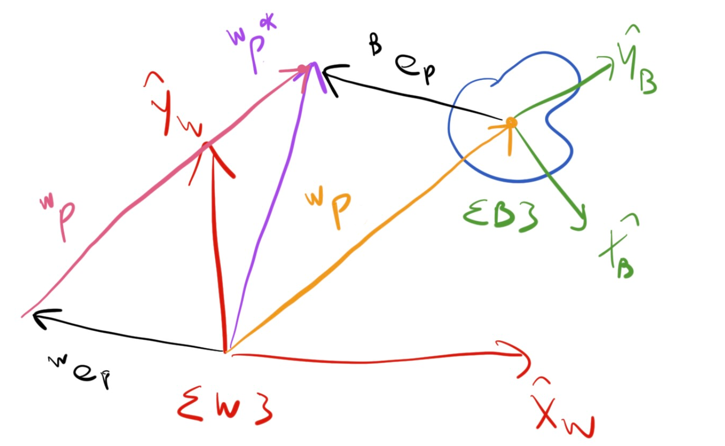

*Figure 2: Vector representation of relationship between world-frame and body-frame position error.*

Using the current pose and desired position, determine the body-frame error.

%Add code here


What you should find is that the world-frame and body-frame position errors are equivalent for the particular configuration (when ${^W{\bf\xi}_B}=[0~~0~~0]^T$).

#### Question 4: Determine the body-frame position error if the orientation is $\psi=\frac{\pi}{2}$.

*Hint: visualise the robot in this pose to ensure that the errors makes physical sense.*

%Code block (if required)


Ensure that you are comfortable with the position errors in both frames. Specifically, when they do and do not match.

## Orientation error

In the case of the differentially-steered robot, we are only concerned with a single rotation angle, $\psi$. As with the world-frame position error, we can define the world-frame orientation error as

${^W{e}_\psi}=\psi^*-\psi$,

where $\psi^*$ is the desired orientation. Given that our wheeled robot can only produce translational velocities in the $\hat{\bf x}_B$ axis, the desired orientation is equivalent to when $\hat{\bf x}_B$ points in the direction of the desired position, ${^W{\bf p}^*}$. This is described mathematically as

$\psi^*=\tan^{-1}\left(\frac{{e_p}_y}{{e_p}_x}\right)$,

where ${e_p}_x$ and ${e_p}_y}$ are the position errors in the $\hat{\bf x}_W$ and $\hat{\bf y}_W$ axes, respectively.

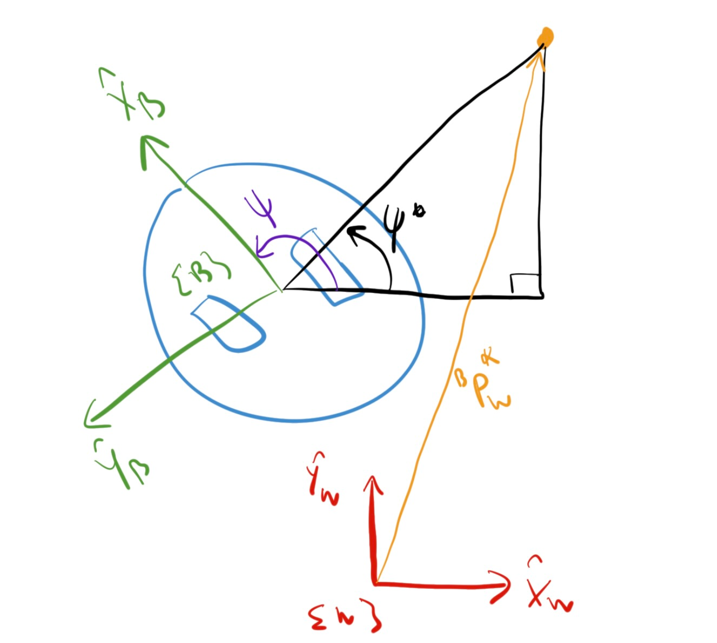

*Figure 3: Vector representation of how *$\psi^*$ is formulated.

Importantly, we must use the `atan2 `function instead of `atan `in general, as the desired orientation will exist in the interval of $\psi^* \in [-\pi,\pi]$, but `atan `only returns angles in the right-half plane quadrants: $[-\pi/2,\pi/2]$.

#### Question 5: Using the initial configuration and desired position from before, determine $\psi^*$.

%Code block (if required)


Ensure that your answer makes sense based on the robot's current configuration and target destination.

## Orientation control

Given that we can specify a desired orientation that is dependent on the world-frame position errors, the next step is to devise a control scheme so that the robot is automatically reoriented correctly. Because $\dot\psi^*$ is the control action that relates to our (desired) angular velocity, it makes sense to affect change here. We will define the control law of

$\dot\psi^*=k_\psi(\psi^*-\psi) = k_\psi\left(\tan^{-1}\frac{{e_p}_y}{{e_p}_x}-\psi\right)$,

where $k_\psi>0$ is our proportional controller gain. Note that when the robot is not in saturation, we will have $\dot\psi=\dot\psi^*$. Based on the structure above, an angular velocity will be commanded until such time that the actual orientation is equal to that of the desired orientation (assuming there are no input disturbances). 

If not saturation is occurring, the settling time of the closed-loop orientation loop is given by


$$t_{\pm 2\%}\approx \frac{4}{k_\psi}.$$


Using the skeleton structure below, add the relevant code to orient the robot such that it points towards the target point. 

- You will need to select an appropriate proportional gain, `k_psi`. 

- Do not command any translational velocity. 

- Use the prescribed variable names. 

- The robot must achieve an orientation error of $|e_\psi|<0.01$ degrees within three seconds.

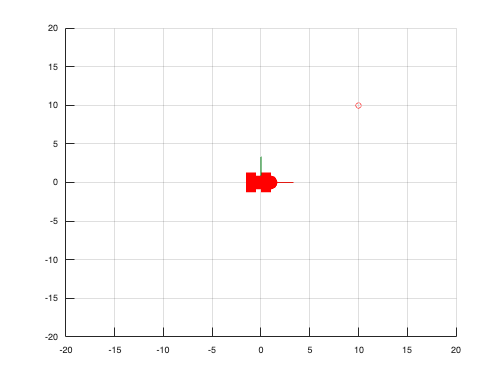

d = 1; %m

r = 0.5; %m
dT = 0.05;
timer = rateControl(1/dT);

%k_psi = ?;
p_des = [10 10]';

p =      0
     0
     0


e_p_wf =     10
    10
     0


robotPose = [0 0 0]';

t = 0;
for i=1:(3/dT)  %run the simulation for a time equivalent to 3 seconds
    figure(1),clf,hold on

    %Add coder here

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;


e_p_bf =     10
   -10
     0


e_p_bf =     10
   -10
     0


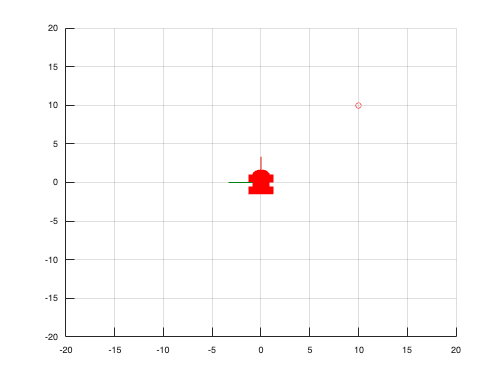

    plotTrVec = [robotPose(1:2); 0];    %extract 2D position of robot
    plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    axis([-20 20 -20 20]),grid on
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);


    p_des = [10 10 0]';
    plot(p_des(1),p_des(2),'ro')

    t = t+dT;
    title(['Time: ',num2str( t ), ' seconds'])
    text(-18,18,{['Orientation error: ',num2str( e_psi*180/pi,'%.2f' ), ' deg a'], ...
                 ['Position error norm: ',num2str( norm(e_p_wf),'%.2f' ), ' m']})

    drawnow
    waitfor(timer);
end


#### Question 6: Upload a .gif or .mp4 of the simulation.

*Hint: use the Export Animation button, found at the bottom right of the figure (applicable to MATLAB versions R2021b+).*

## Position control

The control signal of $v^*$ is used to command forward/reverse velocities in the $\hat{\bf x}_B$-axis. Similar to how we structured our orientation control law to command rotational velocities based on the orientation error, we can adjust $v^*$ using position errors. Importantly, we need to make use of the position error in the $\hat{\bf x}_B$-axis, as $v^*$ can only affect change in that axis. With reference to our previous description of the body-frame position error, the error in the $\hat{\bf x}_B$-axis is defined as

${^Be_x}=\cos(\psi){^We_x}+\sin(\psi){^We_y}$.

The proposed control law follows as


$$\begin{array}{ll}
v^* &=k_v{^Be_x}, \\ 
&=k_v\left( \cos(\psi) 
{^We_x}+\sin(\psi){^We_y} \right),
\end{array}$$


where $k_v>0$ is the proportional gain. If not saturate ever occurs, the forward velocity of the robot will be equal to the desired forward velocity ($v=v^*$) and the settling time of the closed-loop translational loop is approximated by


$$t_{\pm 2\%}\approx \frac{4}{k_v}.$$


We will use the world-frame error norm of


$$||{\bf e}_p||=\sqrt{{e_p}_x^2+{e_p}_y^2}$$


to quantify how close to the target point we are.

Adjust your code so that the position controller is *also* activated during the simulation.

- You will need to select an appropriate combination of `k_psi `and `k_v `based on settling time requirements.

- The wheel saturation levels means that you cannot choose arbitrarily large gain values.

- Ensure that a position error norm of $||{\bf e}_p||<0.2$ metres is obtained within the $3$ second simulation.

- The end orientation error of the robot is inconsequential for this objective.

d = 1; %m

psi_des = 45

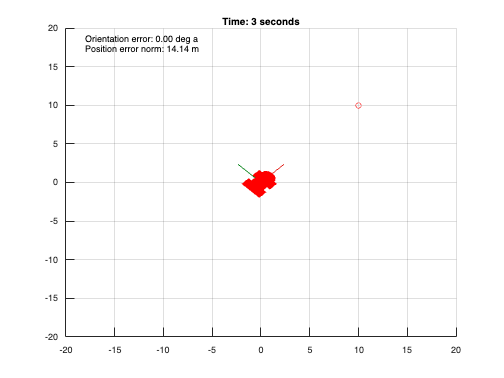

r = 0.5; %m
dT = 0.05;
timer = rateControl(1/dT);

% k_psi = ?;
% k_v = ?;

robotPose = [0 0 0]';

t = 0;
for i=1:(3/dT)  %run the simulation for a time equivalent to 3 seconds
    figure(1),clf,hold on

    %Add code here

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    plotTrVec = [robotPose(1:2); 0];    %extract 2D position of robot
    plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    axis([-20 20 -20 20]),grid on
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);

    p_des = [10 10 0]';
    plot(p_des(1),p_des(2),'ro')

    t = t+dT;
    title(['Time: ',num2str( t ), ' seconds'])
    text(-18,18,{['Orientation error: ',num2str( e_psi*180/pi,'%.2f' ), ' deg a'], ...
                 ['Position error norm: ',num2str( norm(e_p_wf),'%.2f' ), ' m']})

    drawnow
    waitfor(timer);
end


#### Question 7: Upload a .gif or .mp4 of the simulation.

What you should find is that sharing the control bandwidth allocation between the orientation and position feedback loop is not trivial. This is because the maximum wheel speeds of $\pm 20$rad/s means that you cannot simultaneously turn and translate quickly — there is a trade-off between the two. This is especially notable when the robot is initially far from the target point, meaning that the large position error results in large wheel speed requirements. Additionally, when $||{\bf e}_p||$ gets small, the approach of deriving the desired orientation using $\psi^*=\tan^{-1}\left(\frac{{e_p}_y}{{e_p}_x}\right)$ becomes erratic (small changes in the error results in large angle changes).

## Decoupled pose control

While there are more methodical ways to avoid wheel speed saturation, a simple approach for the differentially-steered robot is to first set the orientation such that the robot is pointing towards the target point, and then subsequently only command a translational velocity. In this way, the two control loops become completely decoupled and selection of the two gains becomes a lot easier. Additionally, this removes the issue of having to constantly define a new desired orientation when the error gets small.

- Adjust your code from before so that the position controller only becomes active when the orientation error is less than $|e_\psi|<0.01$ degrees.

- Ensure that a position error norm of $||{\bf e}_p||<0.05$ metres is obtained within the $3$ second simulation.

- The end orientation error of the robot is inconsequential for this objective.

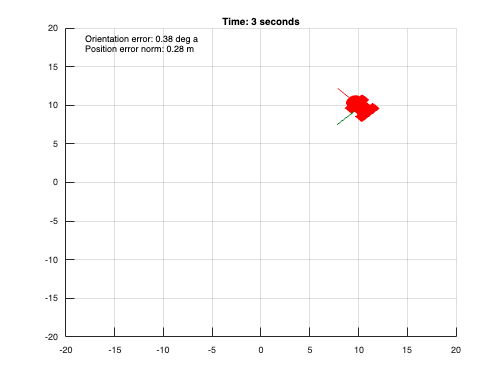

d = 1; %m
r = 0.5; %m
dT = 0.05;
timer = rateControl(1/dT);

% k_psi = ?;
% k_v = ?;

robotPose = [0 0 0]';

psi_des_initial = atan2(p_des(2)-robotPose(2),p_des(1)-robotPose(1));

t = 0;
for i=1:(3/dT)  %run the simulation for a time equivalent to 3 seconds
    figure(1),clf,hold on

    %Add code here

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    plotTrVec = [robotPose(1:2); 0];    %extract 2D position of robot
    plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    axis([-20 20 -20 20]),grid on
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);

    p_des = [10 10 0]';
    plot(p_des(1),p_des(2),'ro')

    t = t+dT;
    title(['Time: ',num2str( t ), ' seconds'])
    text(-18,18,{['Orientation error: ',num2str( e_psi*180/pi,'%.2f' ), ' deg a'], ...
                 ['Position error norm: ',num2str( norm(e_p_wf),'%.2f' ), ' m']})

    drawnow

    waitfor(timer);
end

#### Question 8: Upload a .gif or .mp4 of the simulation.

The target pose used in the previous questions has not explicitly specified a desired orientation. As you should have seen, the final orientation is dictated by the final angle of approach of the target position. 

- Adjust your code from before so that the robot (approximately) achieves a final pose of $\xi=[10~10~\pi/2]^T$ within 3 seconds.

- Ensure that a position error norm of $||{\bf e}_p||<0.05$ metres is obtained within the 3 second simulation.

- The final orientation error must be less than $|e_\psi|<0.01$ degrees.

*Hint: turning on the spot is allowed!*

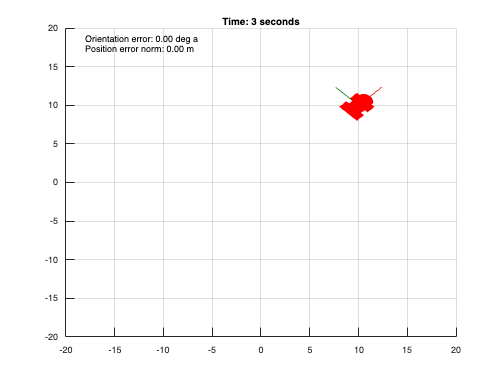

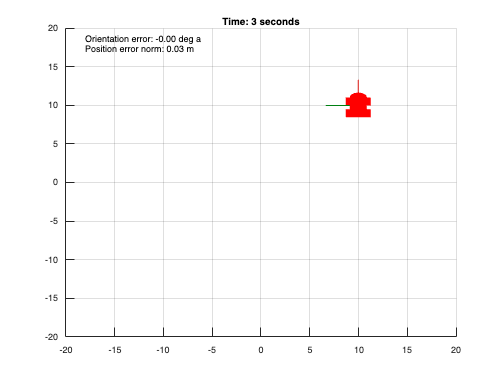

d = 1; %m
r = 0.5; %m
dT = 0.05;
timer = rateControl(1/dT);

% k_psi = ?;
% k_v = ?;

robotPose = [0 0 0]';

t = 0;
for i=1:(3/dT)  %run the simulation for a time equivalent to 3 seconds
    figure(1),clf,hold on

    %Add code here

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    plotTrVec = [robotPose(1:2); 0];    %extract 2D position of robot
    plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    axis([-20 20 -20 20]),grid on
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);

    p_des = [10 10 0]';
    plot(p_des(1),p_des(2),'ro')

    t = t+dT;
    title(['Time: ',num2str( t ), ' seconds'])
    text(-18,18,{['Orientation error: ',num2str( e_psi*180/pi,'%.2f' ), ' deg a'], ...
                 ['Position error norm: ',num2str( norm(e_p_wf),'%.2f' ), ' m']})

    drawnow
    waitfor(timer);
end

#### Question 9: Upload a .gif or .mp4 of the simulation.

#### Question 10: Upload your completed Virtual Lab .mlx file in Amathuba. Make sure to include your student number in the file name.